x = imread('dark2.jpg')

x = 720×1280×3 uint8 배열
x(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1    89    92    89    92    93    74    88    90    94    91    90    86    97    89    78    91    86   100    91    88    86    84    88    93    93    90    87    86    87    92    87    92    84    91    98    83    92    93    92   102    91    99    88    98    96    87    89    95    92    84    88    94    89    83    95    84    90    89    99    99    86    92   105    90    94    80    94    91    88    92    83    81    89    96    94    87    83    90    90    91    91    90    89    88    87    84    92    92    84    94    90    89    88    92    86    90    95    91    90    94    92    

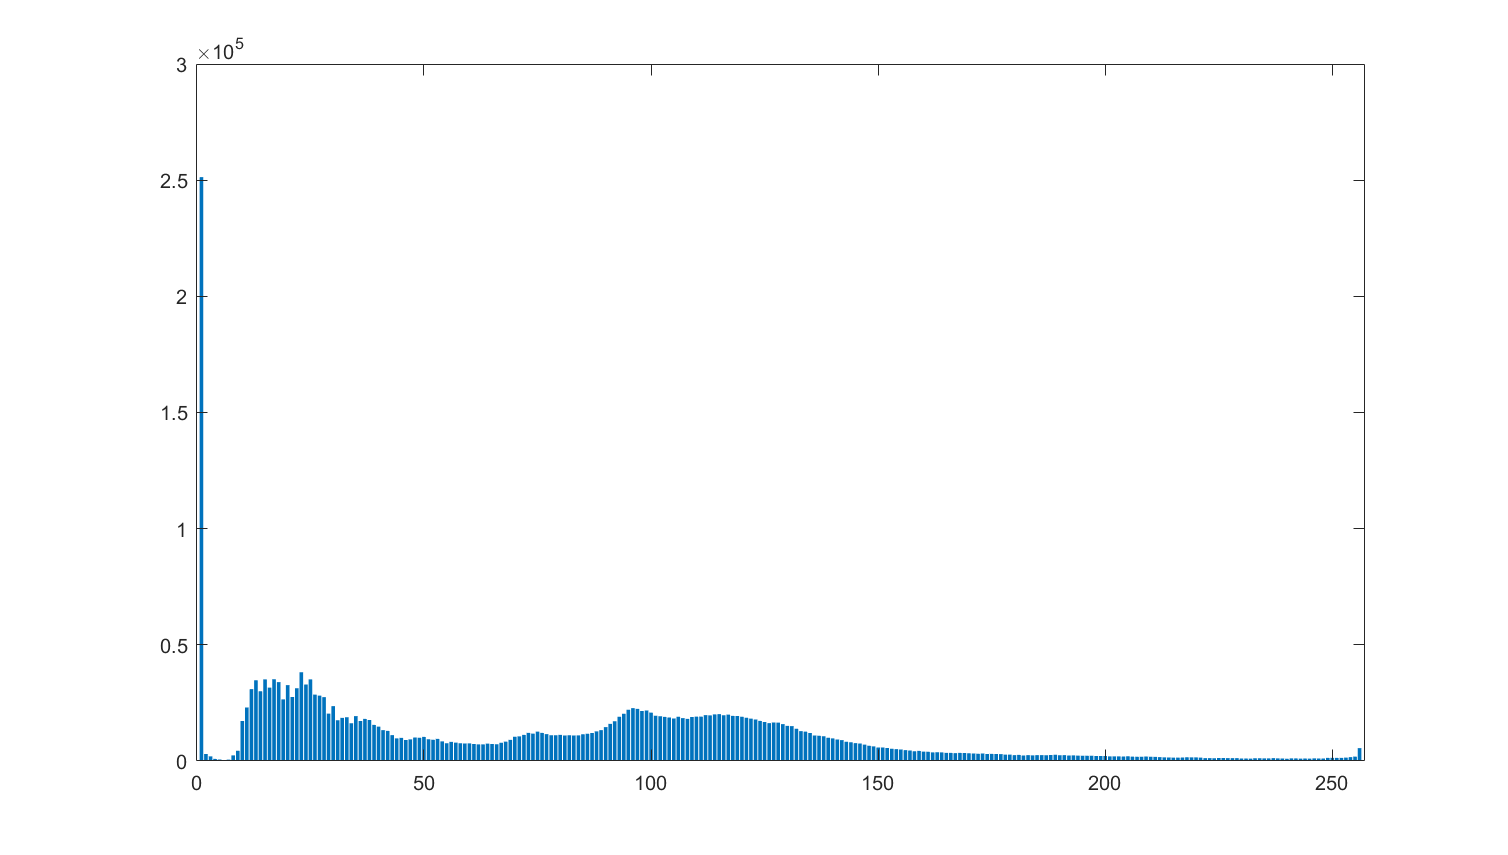


x1 = x - 100;
x2 = x + 100;

h0 = imhist(x);
bar(h0);

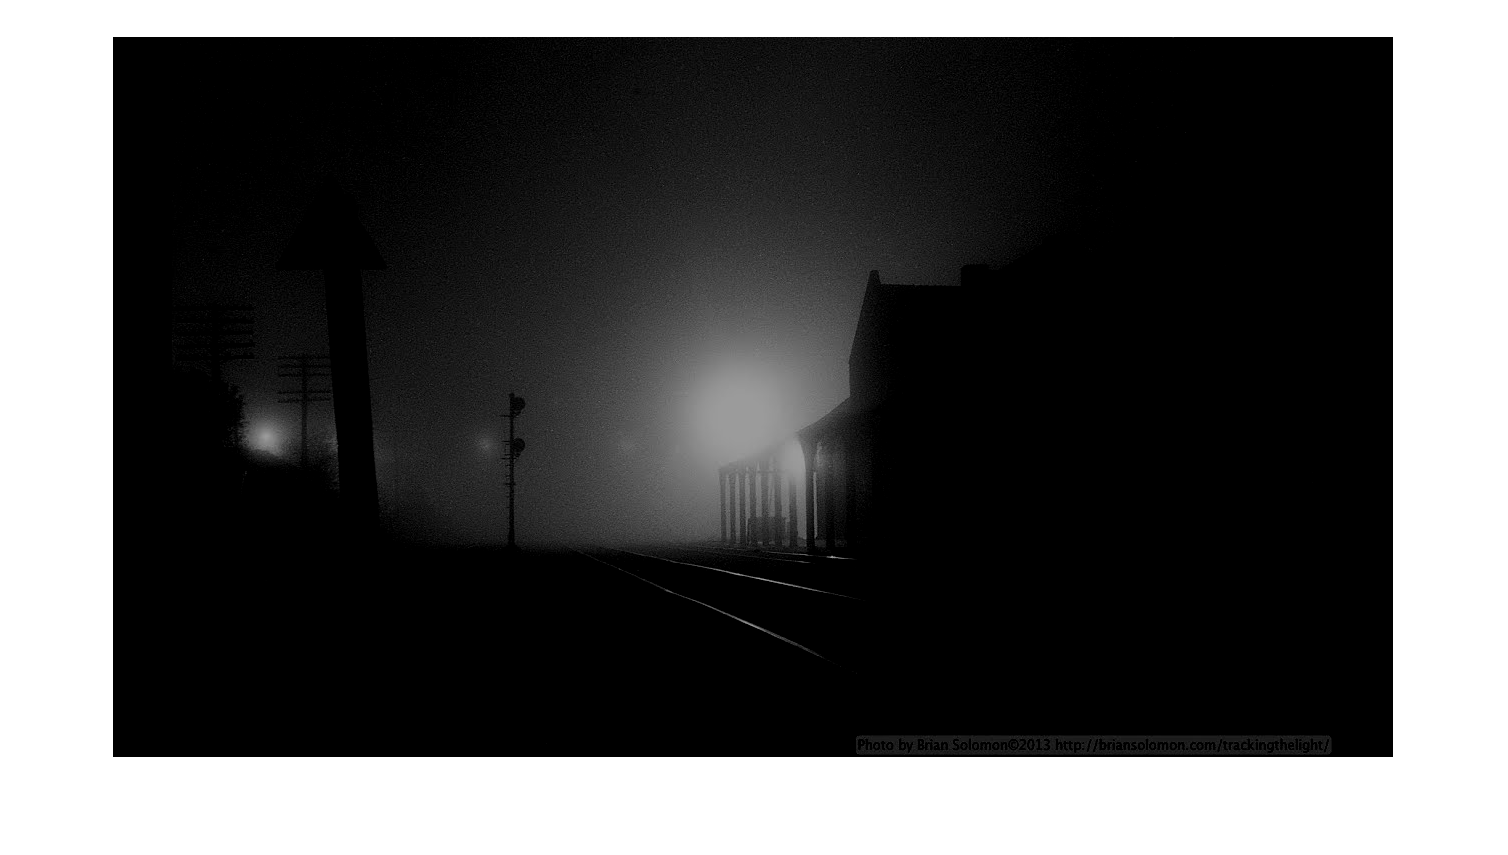

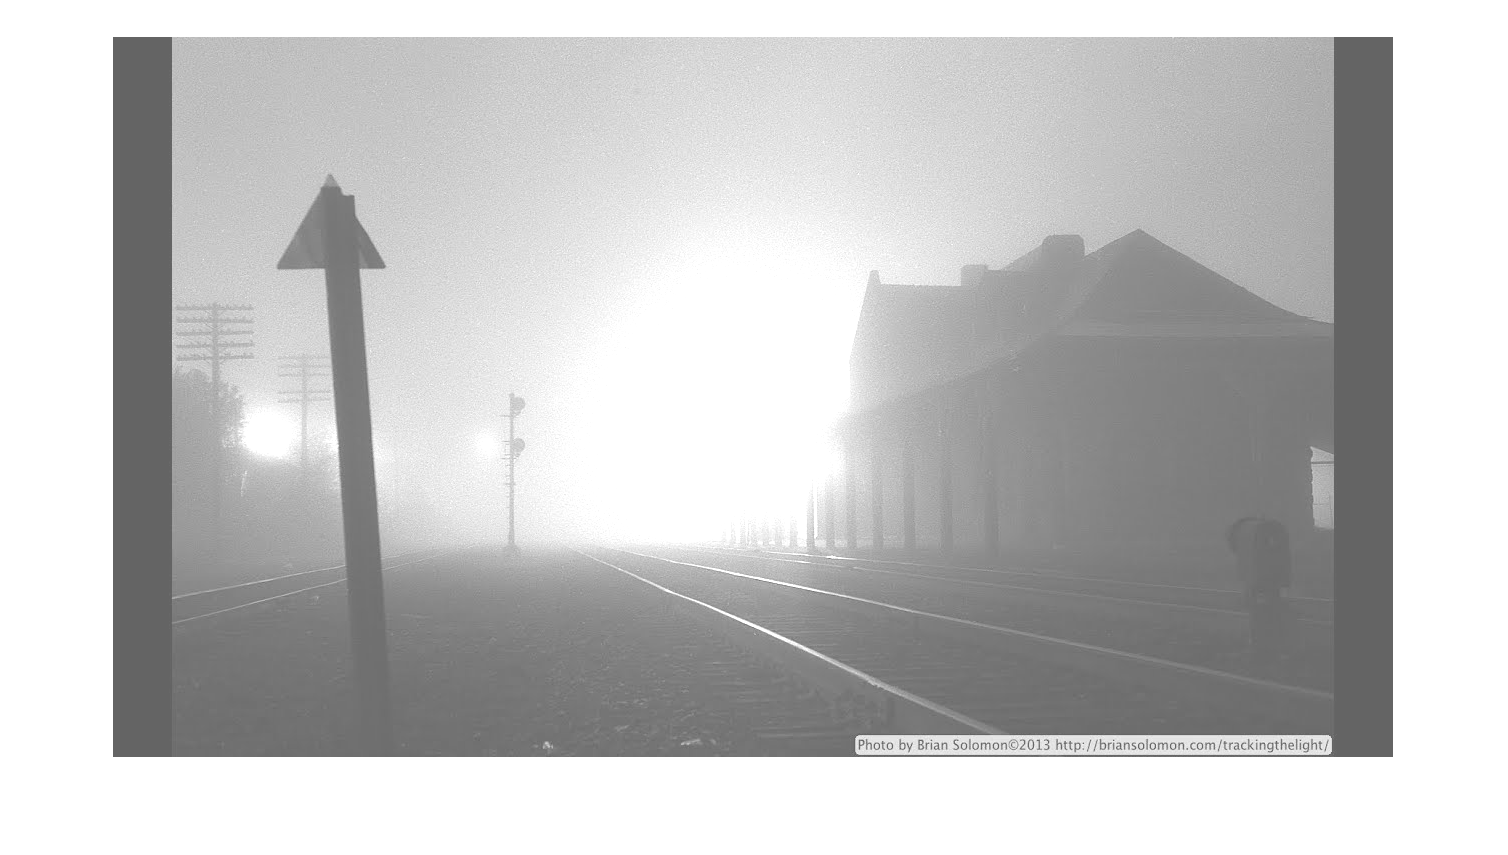


imshow(x), figure(2), imshow(x1), figure(3), imshow(x2)

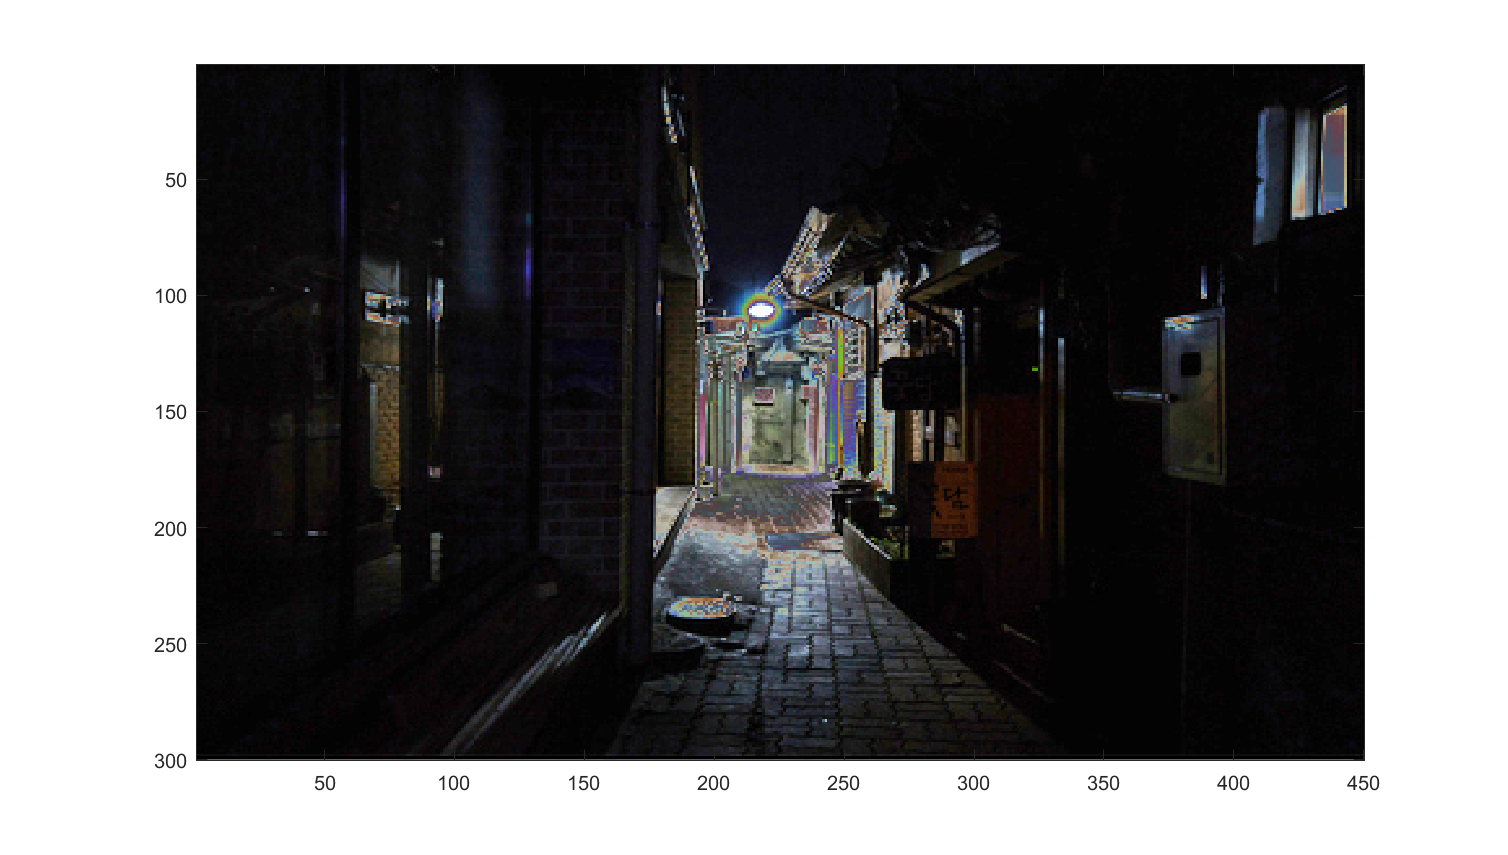


y = histpwl(w, [0, 0.25, 0.5, 0.76, 1], [0, 0.75, 0.25, 0.5, 1]);
figure(5);
imagesc(y); colormap(gray);

function out = histpwl(im, a, b)
classChanged = 0;
if ~isa(im, 'double'),
    classChanged = 1;
    im = im2double(im);
end

if length(a)~=length(b)
    error('Vectors A and B must be of eqaul size');
end

N = length(a);
out = zeros(size(im));

for i=1:N-1
    pix = find(im>=a(i) & im<a(i+1));
    out(pix) = (im(pix)-a(i))*(b(i+1)-b(i))/(a(i+1)-a(i))+b(i);
end

pix = find(im==a(N));
out(pix) = b(N);

if classChanged==1,
    out = uint8(255*out);
end
end